# Hormigón EHE-08

## Ejemplo 1

Este ejemplo consiste en la inicialización del programa, la creación de una sección de hormigón armado, y el análisis de las propiedades calculadas e incluidas en la sección generada. El ejemplo termina con el gráfico del diagrama de interacción de la sección generada.

### Agregar los directorios al *path*

Para comenzar a utilizar el conjunto de funciones del programa se corre el *script* **init.** Este script agrega los directorios  ..\scr\ehe y ....\scr\utils al *path*. Observe que no es necesario copiar las funciones a la carpeta de trabajo.

clear
run('..\init')

### Ingresar la sección de hormigón

A continuación, se ingresa la sección de hormigón armado y/o pretensado. En este ejemplo se trabaja con una sección rectangular de hormigón armado (sin pretensado), con armadura inferior y armadura superior (sin armadura de piel).

En primer lugar, se definen los parámetros de los materiales y de la geometría de la sección a generar.

fck = 30;                       % Resistencia característica a compresión del hormigón (MPa)
fyk = 500;                      % Límite elástico característico del acero (MPa)
b = 150;                        % Ancho de la sección (mm)
h = 400;                        % Alto de la sección (mm)
rm1 = 30;                       % Recubrimiento mecánico inferior (mm)
rm2 = 25;                       % Recubrimiento mecánico superior (mm)
As1 = 3 * pi * (16/2)^2;        % Área de acero inferior, correspondiente a 3 Φ16 mm (mm2)
As2 = 2 * pi * (10/2)^2;        % Área de acero superior, correspondiente a 2 Φ10 mm (mm2)

En segundo lugar, se generan las matrices 'geoHorm' y 'geoAcero' que contienen las propiedades geométricas del hormigón y del acero pasivo. Luego, se crea la sección mediante la función **crear_seccion**. La ayuda de esta función contiene información adicional de cómo se deben generar las matrices 'geoHorm' y 'geoAcero', así como de otros parámetros que pueden añadirse.

geoHorm = [0, b; h, b];                 % Matriz de geometría del hormigón
geoAcero = [rm1, As1; h-rm2, As2];      % Matriz de geometría del acero pasivo

S = crear_seccion(geoHorm, fck, [], geoAcero, fyk);
disp(S)

       geoHorm: [2×2 double]
           fck: 30
            Ec: 2.8577e+04
      geoAcPas: [2×2 double]
           fyk: 500
            Es: 200000
      geoAcAct: []
           fpk: 0
            Ep: 200000
       gamHorm: 1.5000
      gamAcero: 1.1500
    minDivHorm: 100
          yInf: -191.8745
          ySup: 208.1255
             h: 400
          dInf: 370
          dSup: 370
           ec0: -0.0020
           ecu: -0.0035
      nParHorm: 2
          fctm: 2.8965
        fctmfl: 2.8965
           EIb: 2.7133e+13
       eInfAgo: [585×1 double]
       eSupAgo: [585×1 double]
          NAgo: [585×1 double]
          MAgo: [585×1 double]
          NMin: -1.4975e+06
          NMax: 3.3055e+05
          MMin: -1.1668e+08
          MMax: 1.0637e+08
         eInf0: 0
         eSup0: 0



El estructurado 'S' contiene la información ingresada y otras propiedades calculadas, que dependen únicamente de la sección (y no de las solicitaciones actuantes). En lo que queda de este ejemplo se trabaja con la sección generada.

### Obtener propiedades de la sección

El campo 'S.geoHorm' hace referencia a la geometría de la sección ingresada, aunque corregida por el baricentro geométrico. Lo mismo ocurre para el campo 'S.geoAcPas' que contiene la geometría del acero pasivo corregida por el baricentro geométrico. Para modificar este comportamiento, debe cambiarse la sintaxis de la función **crear_seccion** (ver ayuda), de modo que esta no ejecute la función **baricentro_lineal** que corrige la posición el centro de gravedad. 

disp(S.geoHorm)

 -191.8745  150.0000
  208.1255  150.0000



Además de los parámetros ingresados, el estructurado 'S' incluye otra información relativa a los materiales, a la geometría y a las propiedades mecánicas de la sección. Todos los campos usan la nomenclatura de la EHE-08 y unidades N-mm. A continuanción se presentan algunos de las propieades calculadas y almacenadas en 'S'.

fprintf("Resistencia a flexotracción del hormigón: %.2f MPa\n", S.fctmfl)

Resistencia a flexotracción del hormigón: 2.90 MPa


fprintf("Módulo de elasticidad del hormigón: %.2f GPa\n", S.Ec/1e3)

Módulo de elasticidad del hormigón: 28.58 GPa


fprintf("Módulo de elasticidad del acero pasivo: %.2f GPa\n", S.Es/1e3)

Módulo de elasticidad del acero pasivo: 200.00 GPa


fprintf("Factor de seguridad del hormigón: %.2f\n", S.gamHorm)

Factor de seguridad del hormigón: 1.50


fprintf("Factor de seguridad del acero: %.2f\n", S.gamAcero)

Factor de seguridad del acero: 1.15


fprintf("Rigidez bruta de la sección: %.2f kN.m2\n", S.EIb/1e9)

Rigidez bruta de la sección: 27132.52 kN.m2


La rigidez bruta se compara con un cálculo simplificado, en el que se supone que toda la sección es de hormigón.

EIb_simple = S.Ec * b * h^3 / 12;
disp(S.EIb / EIb_simple)

    1.1868



El valor es mayor a 1 porque el cálculo que realiza la función **crear_seccion** mediante la función **rigidez_flexional_bruta** tiene en cuenta la heterogeneidad de la sección (mediante un cálculo lineal).

### Graficar el diagrama de interacción

El estructurado 'S' también incluye un diagrama de interacción de la sección mediante los vectores 'S.NAgo' y 'S.MAgo'. En esta  útlima sección se grafica este diagrama de interacción.

En primer lugar, se asignan variables con diferentes datos del diagrama de interacción en unidades kN-m. El parámetro 'cF' permite modificar que tanto margen se deja entre los bordes del diagrama de interacción y los bordes de la figura.

cF = 0.05;              % Coeficiente para el marco libre de la figura

NMin = S.NMin/1e3;      % Mínima directa (kN) del diagrama de interacción
NMax = S.NMax/1e3;      % Máxima directa (kN) del diagrama de interacción
NAgo = S.NAgo/1e3;      % Vector de directas (kN) del diagrama de interacción
MMin = S.MMin/1e6;      % Mínimo momento flector (kN.m) del diagrama de interacción
MMax = S.MMax/1e6;      % Máximo momento flector (kN.m) del diagrama de interacción
MAgo = S.MAgo/1e6;      % Vector de momentos flectores (kN.m) del diagrama de interacción

NRan = NMax - NMin;     % Rango de directas (kN)
MRan = MMax - MMin;     % Rango de momentos flectores (kN.m)

En segundo lugar, se realiza el gráfico. Obsérvese que el código es relativamente extenso para mejorar la presentación del diagrama de interacción, pero podría reducirse solamente a la última línea.

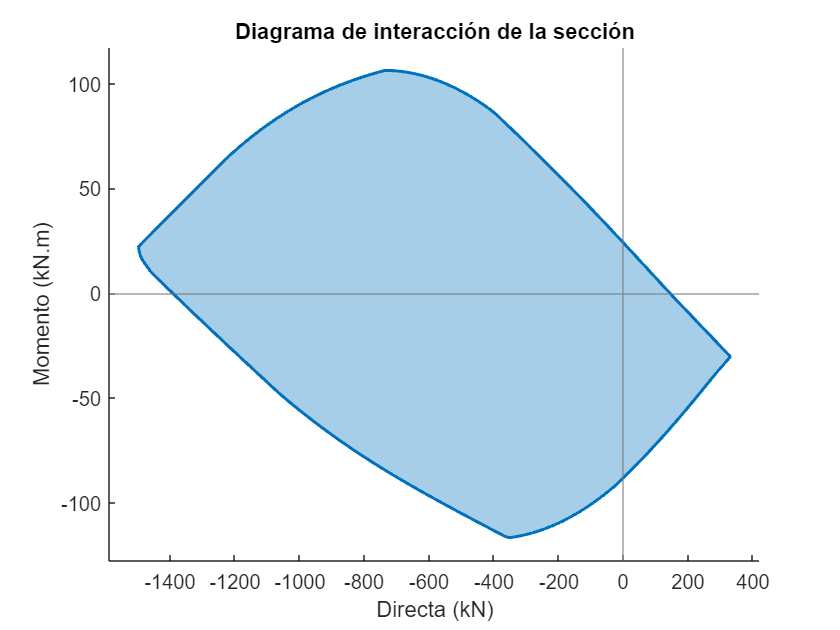

figure
title("Diagrama de interacción de la sección")
xlabel("Directa (kN)")
ylabel("Momento (kN.m)")
xlim([NMin - NRan*cF, NMax + NRan*cF])
ylim([MMin - MRan*cF, MMax + MRan*cF])

hold on
xline(0, "Color", "#777777")
yline(0, "Color", "#777777")
plot(polyshape(NAgo, MAgo, "Simplify", false), "LineStyle", "none")
plot(NAgo, MAgo, "Color", "#0072BD", "LineWidth", 1.5)